clear all
numG = [1]; 		            %Define el numerador de G(s)
denG = [1 +6 +11 +6]; 		    %Define el denominador de G(s)
G = tf(numG,denG);
numH = [-1 -119 -618]; 		            %Define el numerador de G(s)
denH = [1 19 121 257];
H = tf(numH,denH);
GH1 = feedback(G*H,1) 


GH1 =
 
                      -s^2 - 119 s - 618
  -----------------------------------------------------------
  s^6 + 25 s^5 + 246 s^4 + 1198 s^3 + 2986 s^2 + 3434 s + 924
 
Continuous-time transfer function.



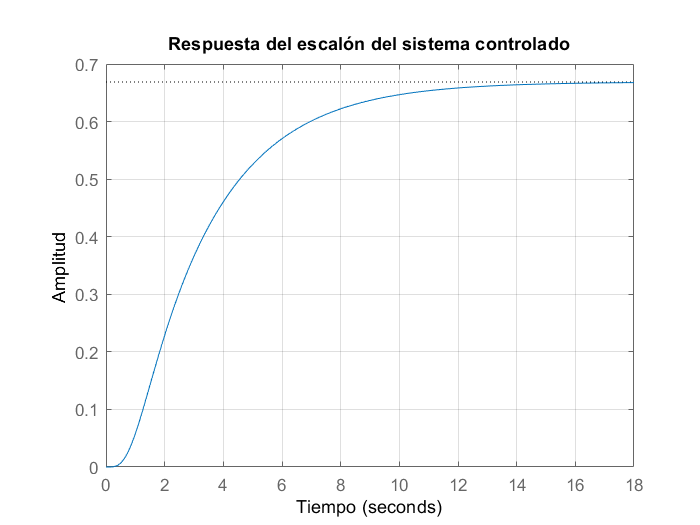

figure(1)                               %Sistema en lazo cerrado
t=0:0.05:500;
step(-GH1)
xlabel('Tiempo') 
ylabel('Amplitud') 
title('Respuesta del escalón del sistema controlado')
grid on

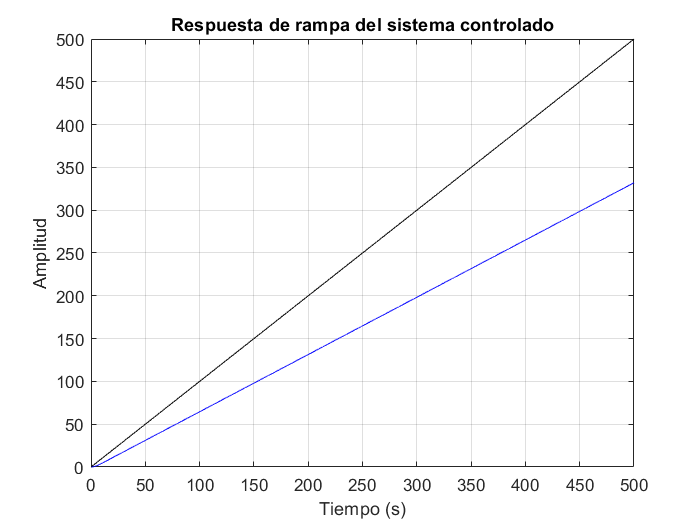

s=tf([1],[1 0]);
c=step(-GH1*s,t);
figure(2)
plot(t,c,'b',t,t,'k')
xlabel('Tiempo (s)') 
ylabel('Amplitud') 
title('Respuesta de rampa del sistema controlado')
grid on

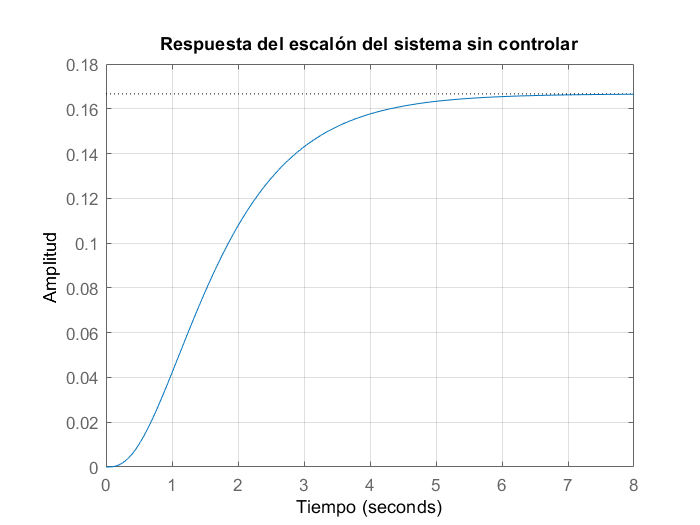

figure(3)                               %Sistema en lazo cerrado
t=0:0.05:500;
step(G)
xlabel('Tiempo') 
ylabel('Amplitud') 
title('Respuesta del escalón del sistema sin controlar')
grid on

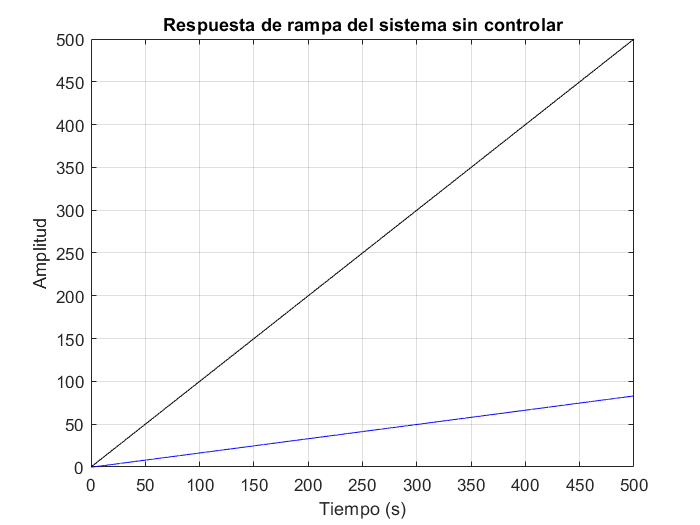

c=step(G*s,t);
figure(4)
plot(t,c,'b',t,t,'k')
xlabel('Tiempo (s)') 
ylabel('Amplitud') 
title('Respuesta de rampa del sistema sin controlar')
grid on